# **Carlos Giral Herrero**

# **PRÁCTICA MATLAB: ADMINISTRACIÓN DE MEDICAMENTOS**

La prescripción de medicamentos es un problema de control. "Toma una pastilla cada 8 horas" es la solución de un problema de lazo abierto. Queremos que la concentración sea suficentemente alta para ser efectiva pero no tanto como para causar efectos secundarios no deseados.

Consideramos dos compartimentos como la siguiente figura:

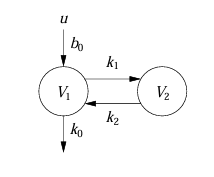

Se busca:

## 1.- Aplicar un balance de materia para determinar las ecuaciones que modelizan el sistema.

El sistema está formado por dos compartimentos de volúmenes $V_1$y $V_2$, con concentraciones $c_1 \left(t\right)$ y $c_{2\;} \left(t\right)$. Ambos compartimentos intercambian flujo mediante un caudal $q$, y del primer compartimento sale además un caudal $q_0$. Existe una entrada controlada $u\left(t\right)$con concentración fija $c_0$.

Para obtener las ecuaciones que describen la dinámica del sistema se aplica un balance de materia en cada compartimento. Lo que se conserva es logicmante el balance entre lo que entra, lo que sale y lo que se acumula.

La cantidad de medicamento en el depósito se define como:


$$\textrm{cantidad}=V_i *c_i \left(t\right)$$


dónde $V_i$ es el volumen del compartimento y $c_i \left(t\right)$ su concentración.

El principio de conservación establece: 


$$\frac{d}{\textrm{dt}}\left(\textrm{cantidad}\right)=\textrm{entradas}-\textrm{salidas}$$


Como el volumen es constante:


$$\frac{d}{\textrm{dt}}\left(V_i *c_i \right)=V_i *\overset{\ldotp }{c_i }$$


Las entradas y salidas se obtienen multiplicando cada caudal por la concentración del fluido transportado. 

### **ECUACIÓN DEL PRIMER COMPARTIMENTO**


$$V_1\,\dot c_1(t) = q\,[c_2(t) - c_1(t)] - q_0\,c_1(t) + c_0\,u(t)$$


### **ECUACIÓN DEL SEGUNDO COMPARTIMENTO**


$$V_2\,\dot c_2(t) = q\,[c_1(t) - c_2(t)]$$


Una vez planteadas las ecuaciones de balance en su forma original, definimos las constantes cinéticas:


$$\(
k_0 = \frac{q_0}{V_1}, \quad
k_1 = \frac{q}{V_1}, \quad
k_2 = \frac{q}{V_2}, \quad

b_0 = \frac{c_0}{V_1}.
\)$$


Sustituyendo en las ecuaciones del sistema, obtenemos el modelo normalizado:


$$\(
\dot c_1(t) = -(k_1 + k_0)\,c_1(t) + k_2\,c_2(t) + b_0\,u(t)
\)
$$



$$
\(
\dot c_2(t) = k_1\,c_1(t) - k_2\,c_2(t)
\)$$


## 2.- Identifica las matrices de estado, de controles y de salida. 

Una vez obtenidas las ecuaciones diferenciales del sistema, podemos expresarlo en la representación estándar de espacio de estados, definida por:


$$\dot x(t) = A\,x(t) + B\,u(t)$$



$$y(t) = C\,x(t) + D\,u(t)$$


donde:

- $x\left(t\right)$ es el vector estado.

- $u\left(t\right)$ es la entrada.

- $y\left(t\right)$ es la salida.

- $A,B\;,D\;y\;D$ son las matrices que caracterizan a la dinámica del sistema.

Vector estado: se toman como estados las concentraciones en ambos compartimentos.


$$x(t) =
\left[
\begin{array}{c}
c_1(t) \\
c_2(t)
\end{array}
\right]$$


Entrada:


$$u(t)=u(t)$$


Salida:


$$y(t)=c_2(t)$$


Por tanto:

- Matriz A - Matriz de estado:


$$A =
\left[
\begin{array}{cc}
-\left(\frac{q}{V_1} + \frac{q_0}{V_1}\right) & \frac{q}{V_1} \\
\frac{q}{V_2} & -\frac{q}{V_2}
\end{array}
\right]$$



$$A =
\left[
\begin{array}{cc}
-(k_0 + k_1) & k_1 \\
k_2 & -k_2
\end{array}
\right]$$


- Matriz B - Matriz de control:


$$B =
\left[
\begin{array}{c}
\frac{c_0}{V_1} \\
0
\end{array}
\right]$$



$$B =
\left[
\begin{array}{c}
b_0 \\
0
\end{array}
\right]$$


- Matriz C - Matriz de salida:


$$C =
\left[
\begin{array}{cc}
0 & 1
\end{array}
\right]$$


- Matriz D - Matriz de transmisión directa:


$$D =
0$$


## 3.- Sean $k_0 =0\ldotp 1$, $k_1 =0,1$, $k_2 =0,5$ y $b_0 =1,5$ --> Calcula la función de transferencia.

Sustituimos en las matrices:


$$A =
\left[
\begin{array}{cc}
-(k_0 + k_1) & k_1 \\
k_2 & -k_2
\end{array}
\right]
=
\left[
\begin{array}{cc}
-(0.1 + 0.1) & 0.1 \\
0.5 & -0.5
\end{array}
\right]
=
\left[
\begin{array}{cc}
-0.2 & 0.1 \\
0.5 & -0.5
\end{array}
\right]$$



$$B =
\left[
\begin{array}{c}
b_0 \\
0
\end{array}
\right]
=
\left[
\begin{array}{c}
1.5 \\
0
\end{array}
\right]$$



$$C = 
\left[
\begin{array}{cc}
0 & 1
\end{array}
\right],
\qquad
D = 0$$


La función de transferencia se obtiene aplicando la Transformada de Laplace al modelo en espacio de estados con condiciones iniciales nulas. De este modo, la relación entre la entrada y la salida queda dada por la expresión estándar:


$$G(s) = C\,(sI - A)^{-1} B + D= C\,(sI - A)^{-1} B$$


Cálculo de $\textrm{sI}-A$:


$$sI - A =
\left[
\begin{array}{cc}
s + 0.2 & -0.1 \\
-0.5 & s + 0.5
\end{array}
\right]$$


Matriz 2x2 --> ${\left(\textrm{sI}-A\right)}^{-1} =\frac{\textrm{adj}\left(\textrm{sI}-A\right)}{\det \left(\textrm{sI}-A\right)}$

Denominador:


$$\Delta(s)
= (s + 0.2)(s + 0.5) - (-0.1)(-0.5)=  s^2 + 0.7s + 0.05$$


Numerador:


$$\text{adj}(sI - A)
=
\left[
\begin{array}{cc}
s + 0.5 & 0.1 \\
0.5 & s + 0.2
\end{array}
\right]$$



$$\text{adj}(sI - A)\; B
=
\left[
\begin{array}{c}
1.5(s + 0.5) \\
0.75
\end{array}
\right]$$



$$C \; \mathrm{Adj}(sI - A) \; B
=
0.75$$


Finalmente obtenemos:


$$G(s) = 
\frac{0.75}{
\left( s^2 + 0.7s + 0.05 \right)
}$$


## 4.- Dibuja la respuesta cuando la administración del medicamento se realiza mediante una inyección.

Se consideran dos modelos diferentes: Inyección ideal (modelo impulso) e inyección realista (pulso rectangular corto). 

Una inyección administrada de forma instantánea puede modelarse matemáticamente como un impulso de Dirac $\delta \left(t\right)$. Este tipo de entrada no es físicamente realizable: ningún proceso real puede introducir una cantidad finita de medicamento en un tiempo estrictamente nulo.

Sin embargo, el impulso es extremadamente útil como aproximación idealizada porque:

- representa una entrada muy concentrada en el tiempo,

- permite obtener directamente la respuesta impulsional del sistema,

- y simplifica los cálculos en el dominio de Laplace, ya que su transformada es $U\left(s\right)=1$.

En la práctica, una inyección siempre tiene una duración finita, por pequeña que sea; por este motivo, además del caso ideal, se modela también una inyección realista mediante un pulso rectangular corto que aproxima la administración rápida pero no instantánea. 

Para representar un equivalente físico del Dirac, se emplea un pulso rectancular muy breve cuya área sea aproximadamente 1, ya que:


$$\(
\int_{0^-}^{0^+} \delta(t)\, dt = 1
\)$$


Escogemos:


$$\(
u_0 = 5, \qquad T_p = 0.2\,\text{s}
\)$$


Condición de equivalencia con Dirac:


$$\(
u_0\, T_p = 1
\)$$


Además, al trabajar en Matlab, se resolverá directamente las ecuaciones diferenciales, a pesar de haber obtenido la función de transferencia, muy útil para resolver a mano.

%set(groot,'defaultFigureColor','white');
%%definimos el sistema
k0=0.1;
k1=0.1;
k2=0.5;
b0=1.5;
A=[-(k1+k0), k1;
    k2 ,    -k2];
B=[b0;
    0];
C=[0 1];
D=0;
system = ss(A,B,C,D);

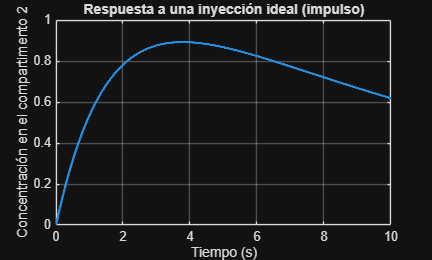

%% Respuesta a una inyección ideal (impulso)
system = ss(A,B,C,D);t = linspace(0,10,2000);
[y_imp, t_imp] = impulse(system, t);

plot(t_imp, y_imp,'LineWidth',1.8)
grid on
xlabel('Tiempo (s)')
ylabel('Concentración en el compartimento 2')
title('Respuesta a una inyección ideal (impulso)')

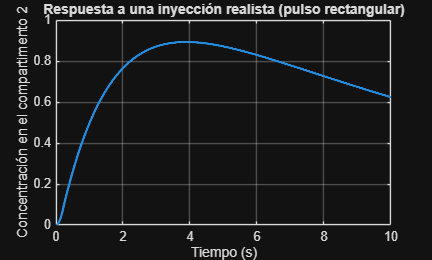

%% Respuesta a un pulso rectangular (inyección realista)

Tp = 0.2;      % Duración del pulso
u0 = 5;        % Intensidad del pulso
t = linspace(0,10,2000);

u = (t <= Tp) * u0;  % pulso rectangular

[y_pulse, t_pulse, x_pulse] = lsim(system, u, t);

plot(t_pulse, y_pulse,'LineWidth',1.8)
grid on
xlabel('Tiempo (s)')
ylabel('Concentración en el compartimento 2')
title('Respuesta a una inyección realista (pulso rectangular)')

La similitud entre ambas respuestas es completamente esperable: el pulso rectangular utilizado tiene una duración muy pequeña en comparación con las constantes de tiempo del sistema. Desde el punto de vista de la dinámica, una entrada tan rápida es practicamente indistinguible de un impulso ideal.

Además, ambos estímulos aportan la misma cantidad total de medicamento. Mientras el pulso sea lo suficientemente estrecho, el sistema "no tiene tiempo" a reaccionar de forma exacta y solo percibe la cantidad total administrada.  

## 5.- Supongamos ahora que el medicamento se administra por gotero constante u = 0.1 cl/s. ¿Cuál es el valor de la salida de estado estacionario? ¿y cuánto tiempo se tarda en que la respuesta alcance y se mantenga en un 2% de dicho valor?

El sistema que tenemos es lineal e invariante en el tiempo. Para una entrada constante, el estado estacionario se obtiene imponiendo $0=Ax_{\textrm{ss}} +B\;u$.


$$0=Ax_{\textrm{ss}} +B\;u$$



$$x_{\textrm{ss}} =-A^{-1} B\;u$$


Siendo la salida:


$$y_{\textrm{ss}} =Cx_{\textrm{ss}}$$


Ahora resolvemos las ecuaciones:


$$\det(A) = (-0.2)(-0.5) - (0.1)(0.5) = 0,05$$



$$A^{-1}
= \frac{1}{0.05}
\left[ \begin{array}{cc}
-0.5 & -0.1 \\
-0.5 & -0.2
\end{array} \right]

= \left[ \begin{array}{cc}
-10 & -2 \\
-10 & -4
\end{array} \right]$$



$$A^{-1} B
=
\left[ \begin{array}{cc}
-10 & -2 \\
-10 & -4
\end{array} \right]
\left[ \begin{array}{c}
1.5 \\
0
\end{array} \right]
=
\left[ \begin{array}{c}
-15 \\
-15
\end{array} \right]$$



$$x_{ss}
= -0.1
\left[ \begin{array}{c}
-15 \\
-15
\end{array} \right]
=
\left[ \begin{array}{c}
1.5 \\
1.5
\end{array} \right]$$



$$y_{ss}
=
\left[ \begin{array}{cc}
0 & 1
\end{array} \right]
\left[ \begin{array}{c}
1.5 \\
1.5
\end{array} \right]
= 1.5 \ g/cl$$


Para determinar si la salida puede aproximarse al valor estacionario dentro de un margen del 2 %, y en su caso calcular el tiempo necesario, es preciso analizar la dinámica del sistema.

Esta dinámica está gobernada por los autovalores de la matriz A, ya que ellos controlan los modos exponenciales que aparecen en la respuesta.

Si algún autovalor tuviera parte real no negativa, la salida no podría converger al estado estacionario y el tiempo de establecimiento no existiría. En caso de que todos sean negativos, la parte transitoria desaparecerá con una velocidad determinada por el modo dominante (el autovalor más cercano a cero).

Calculamos por tanto los autovalores de A para identificar dicho modo dominante y, si el sistema es estable, obtener el tiempo de establecimiento:


$$\det \left(
\left[ \begin{array}{cc}
\lambda + 0.2 & -0.1 \\
-0.5 & \lambda + 0.5
\end{array} \right]
\right) = 0$$



$$(\lambda + 0.2)(\lambda + 0.5) - (0.1)(0.5) = 0$$



$$\lambda^2 + 0.7\lambda + 0.1 - 0.05 = 0$$



$$\lambda^2 + 0.7\lambda + 0.05 = 0$$



$$\lambda = \frac{-0.7 \pm \sqrt{0.7^2 - 4(0.05)}}{2}$$



$$\lambda = \frac{-0.7 \pm \sqrt{0.49 - 0.2}}{2}$$



$$\lambda = \frac{-0.7 \pm \sqrt{0.29}}{2}$$



$$\lambda_1 \approx -0.064$$



$$\lambda_2 \approx -0.636$$


Ambos autovalores tienen parte real negativa, por lo que el sistema puede converger al estado estacionario.

El autovalor dominante es $\lambda =-0\ldotp 064$ ya que es el más cercano a cero y, por tanto, el que decae más lentamente. Este modo domina el comportamiento transitorio del sistema y determina el tiempo de establecimiento.

Utilizamos la fórmula estándar del tiempo de establecimiento al 2 % para sistemas LTI de primer orden o dominados por un único modo, que se expresa como:


$$T_{2\%} \approx \frac{4}{|\lambda_d|}$$


Sustituimos:


$$T_{2\%} \approx \frac{4}{0.064}$$



$$T_{2\%} \approx 62.5\ \text{s}$$


La salida del sistema alcanza el 98 % del valor estacionario y se mantiene dentro del margen del 2 % aproximadamente a los 62.5 segundos.

Este tiempo está determinado por el autovalor dominante, que controla la velocidad de desaparición de la parte transitoria.

## 6.- Compara gráficamente la respuesta de este sistema con la respuesta si se administrara la medicación según un pulso de 5 segundos de duracion y amplitud 0.3 cl/s y después se mantuviera a 0.1 cl/s. ¿Qué respuesta es más rápida?

Para comparar la rapidez con la que evoluciona la concentración en el compartimento 2 bajo diferentes pautas de administración, analizamos la respuesta del sistema ante dos entradas distintas.

En primer lugar, consideramos la administración continua del medicamento con un caudal constante de $u\left(t\right)=0\ldotp 1$cl/s, tal como en el apartado anterior.

A continuación, estudiamos un segundo escenario en el que se administra un **pulso inicial** de mayor intensidad: un caudal de 0.3 cl/s durante los primeros 5 segundos, seguido de 0.1 cl/s para el resto del tiempo. Esta pauta permite observar cómo una dosis inicial más elevada acelera la subida de concentración.

Para comparar ambas situaciones de forma clara, simulamos numéricamente la respuesta del sistema con cada entrada y representamos las dos curvas en la misma figura.

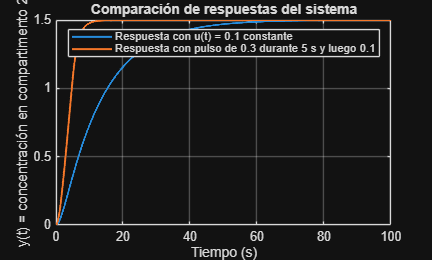

%% Apartado 6: Comparación de respuestas

% Matrices del sistema
A = [-0.2  0.1;
      0.5 -0.5];
B = [1.5;
     0   ];
C = [0 1];
D = 0;

% Definimos el sistema LTI
sys = ss(A,B,C,D);

%% Caso 1: Entrada constante u(t) = 0.1 cl/s
t_final = 100;                 % tiempo suficiente para ver asentamiento
t = linspace(0,t_final,5000);  % vector de tiempo
u1 = 0.1*ones(size(t));        % entrada constante

[y1,~] = lsim(sys,u1,t);

%% Caso 2: Pulso de 5 s a 0.3, luego 0.1
u2 = 0.1*ones(size(t));
u2(t <= 5) = 0.3;

[y2,~] = lsim(sys,u2,t);

%% Gráfica comparativa
figure;
plot(t,y1,'LineWidth',1.5); hold on;
plot(t,y2,'LineWidth',1.5);
grid on;
xlabel('Tiempo (s)');
ylabel('y(t) = concentración en compartimento 2');
title('Comparación de respuestas del sistema');
legend('Respuesta con u(t) = 0.1 constante',...
       'Respuesta con pulso de 0.3 durante 5 s y luego 0.1');

Como se observa en las gráficas, la respuesta correspondiente a la entrada con un pulso inicial de 0.3 cl/s alcanza antes el valor estacionario.

Este comportamiento era esperable: durante los primeros 5 segundos la entrada del sistema es mayor que en el caso de 0.1 cl/s constante, lo que provoca que la concentración en el compartimento 2 aumente más rápidamente.

Una vez finalizado el pulso, ambas entradas coinciden en 0.1 cl/s, de modo que ambas respuestas tienden al mismo valor estacionario, pero la que recibió la dosis inicial mayor lo hace de forma más rápida.

## 7.- ¿Es el sistema estable?

Para analizar la estabilidad del sistema consideramos los autovalores de la matriz AAA obtenidos en el apartado anterior:


$$\lambda_1 \approx -0.064$$



$$\lambda_2 \approx -0.636$$


Ambos autovalores tienen parte real negativa, por lo que el sistema es estable en el sentido de Lyapunov.

En consecuencia, la respuesta del sistema con entrada constante converge al valor estacionario calculado previamente.

## 8. ¿Es el sistema controlable?

Para comprobar la controlabilidad del sistema construimos la matriz de Kalman:


$$\mathcal{C} =
\left[
\begin{array}{cc}
B & AB
\end{array}
\right]$$



$$B =
\left[
\begin{array}{c}
1.5 \\
0
\end{array}
\right]$$



$$AB =
\left[
\begin{array}{cc}
-0.2 & 0.1 \\
0.5 & -0.5
\end{array}
\right]
\left[
\begin{array}{c}
1.5 \\
0
\end{array}
\right]
=
\left[
\begin{array}{c}
-0.3 \\
0.75
\end{array}
\right]$$



$$\mathcal{C} =
\left[
\begin{array}{cc}
1.5 & -0.3 \\
0   & 0.75
\end{array}
\right]$$



$$\det(\mathcal{C}) = 1.5 \cdot 0.75 = 1.125 \neq 0$$


Como la matriz de controlabilidad tiene determinante distinto de cero (rango completo), el sistema es completamente controlable.

## Suponemos ahora que podemos medir las concentraciones del medicamento en cada compartimento. Queremos diseñar un feedback de estados para, por una parte, mantener la salida en el valor 1 y, por otra, que $\zeta$ tome el valor de 0.9 para minimizar la sobreelongación, y $\omega_0 \;$tome el valor 0,22, lo cual produce un tiempo de subida de 10 segundos, es decir, queremos encontrar una ley de control que haga que la matriz de estados del sistema en lazo cerrado tenga polinomio característico $\lambda^2 +2*0\ldotp 9*0\ldotp 22+{0\ldotp 22}^2$.

## 9.- ¿Qué matriz de feedback nos permite conseguirlo?

Queremos encontrar una matriz de realimentación (K):


$$u\left(t\right)=-K*x\left(t\right)+r$$


tal que la matriz de lazo cerrado:


$$A_{\textrm{cl}} =A-B\;K$$


tenga el polinomio característico deseado:


$$\lambda^2 +2\zeta \omega_0 \lambda +{w_0 }^2$$


dónde:


$$\zeta =0\ldotp 9$$



$$w_0 =0\ldotp 22$$


y por tanto:


$$\lambda^2 + 2*0.9*0.22 * \lambda + (0.22)^2$$



$$\lambda^2 + 0.396 * \lambda + 0.0484^2$$


Polos deseados:


$$\lambda_{1,2}
=
\frac{-0.396 \pm \sqrt{0.396^2 - 4*(0.0484)}}{2}$$


Ecuación del lazo cerrado:


$$A_{\text{cl}} = A - BK$$


Condición de asignación de polos:


$$\det\!\left( \lambda I - (A - BK) \right)
=
\lambda^2 + 0.396\,\lambda + 0.0484$$


Lo calculamos:

%% Apartado 9: Cálculo de la matriz K

A = [-0.2  0.1;
      0.5 -0.5];
B = [1.5;
     0   ];

% Polos deseados del polinomio λ² + 0.396λ + 0.0484
polos = roots([1 0.396 0.0484]);

% Cálculo de K por asignación de polos
K = place(A,B,polos)

K =    -0.2027    0.2005


La matriz de feedbak sería:


$$K = \left[ \begin{array}{cc}
-0.2027 & 0.2005
\end{array} \right]$$


## 10.- Es el sistema resultante estable?

Los autovalores del sistema en lazo cerrado son:


$$\lambda_{1,2} = -0.1980 \pm 0.0957 i$$


los cuales tienen parte real estrictamente negativa, el sistema en lazo cerrado es asintóticamente estable por construcción.

## 11.- Cual es la salida del controlador, es decir, cual es la entrada al sistema.

Nos piden ahora la entrada al sistema en lazo cerrado:


$$u\left(t\right)=-K*x\left(t\right)+r$$


Queremos que la salida final sea 1. Tenemos que encontrar el valor del término constante r que garantice ese valor de salida.

El sistema en lazo cerrado es:


$$\overset{\ldotp }{x} =\left(A-B\;K\right)x+B\;r$$



$$y=C\;x$$


En regimen estacionario:


$$0=\left(A-B\;K\right)x_{\textrm{ss}} +B\;r$$


Y además queremos:


$$y_{\textrm{ss}} =C\;x_{\textrm{ss}} =1$$


Luego, tenemos que resolver:


$$r=-{\left(C{\left(A-B\;K\right)}^{-1} \;B\right)}^{-1} *1$$


A = [-0.2 0.1;
     0.5 -0.5];
B = [1.5;
     0];
C = [0 1];

K = [-0.2027 0.2005];   

Acl = A - B*K;

% Queremos y_ss = 1
y_obj = 1;

r = -( C * (Acl \ B) ) \ y_obj

r = 0.0645


$$u(t) = -[-0.2027 \;\; 0.2005]\, x(t) + 0.0645$$


## 12. Queremos comparar la respuesta al salto unidad del sistema en lazo cerrado anterior (que calcula las dosis del medicamento a administrar continuamente), con la respuesta del sistema en lazo abierto cuando se administran dosis periodicas de valor 0.7 cl/s durante 1 segundo cada 10 segundos. Para ello dibuja en la misma ventana por un lado una gráfica con las entradas en cada caso y, por otro, una gráfica con las respuestas del sistema en cada caso. Haz la simulacion durante 60 segundos.

Se compara la respuesta del sistema en lazo cerrado, que aplica de forma continua a la ley de control $u\left(t\right)=-K\;x+r$ con la respuesta del sistema en lazo abierto, en la que las dosis se administran mediante pulsos periódicos de 0.7 cl/s durante 1s cada 10 s. Para ver esto, se va a simular el sistema durante 60 s, representando en la misma figura las entradas aplciadas en ambos casos y, en otra gráfica, lassalidas resultantes. Esto permite visualizar la diferencia entre un control continuo (lazo cerrado) y una administración intermitente (lazo abierto):

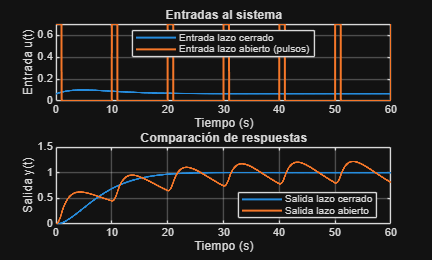

%% Comparación entre lazo cerrado y lazo abierto

% Sistema
A = [-0.2 0.1;
      0.5 -0.5];
B = [1.5;
     0];
C = [0 1];
D = 0;

% Controlador
K = [-0.2027 0.2005];
r = 0.0645;

% Tiempo de simulación
t = 0:0.01:60;

%% --- 1. ENTRADA EN LAZO CERRADO ---
% u_cl = -Kx + r

% Simulamos el sistema en lazo cerrado como sistema dinamico:
Acl = A - B*K;
Bcl = B*r;     % entrada efectiva constante debido a r

sys_cl = ss(Acl, Bcl, C, D);

% Simulación en lazo cerrado: obtenemos y(t), t y los estados x(t)
[y_cl, t_cl, x_cl] = lsim(sys_cl, ones(size(t)), t);

% Entrada REAL del controlador
u_cl = (-K * x_cl.' + r).';   % convertir a vector columna

%% --- 2. ENTRADA EN LAZO ABIERTO: PULSOS DE 0.7 CL/S ---
u_ol = zeros(size(t));
for i = 1:length(t)
    if mod(t(i),10) < 1
        u_ol(i) = 0.7;
    end
end

sys_ol = ss(A,B,C,D);
[y_ol, ~, ~] = lsim(sys_ol, u_ol, t);

%% --- 3. GRAFICAS ---

figure;

subplot(2,1,1)
plot(t, u_cl, 'LineWidth',1.5); hold on;
plot(t, u_ol, 'LineWidth',1.5);
legend('Entrada lazo cerrado','Entrada lazo abierto (pulsos)','Location','Best');
xlabel('Tiempo (s)');
ylabel('Entrada u(t)');
title('Entradas al sistema');
grid on;

subplot(2,1,2)
plot(t, y_cl, 'LineWidth',1.5); hold on;
plot(t, y_ol, 'LineWidth',1.5);
legend('Salida lazo cerrado','Salida lazo abierto','Location','Best');
xlabel('Tiempo (s)');
ylabel('Salida y(t)');
title('Comparación de respuestas');
grid on;

## 13.-¿Qué puedes deducir a la vista de las gráficas anteriores?

La comparación de las gráficas muestra claramente la diferencia entre la dinámica en lazo cerrado y en lazo abierto. En lazo cerrado, la realimentación permite que el sistema ajuste continuamente la entrada para compensar el error y mantener la salida próxima al valor deseado. La respuesta es estable, suave y converge de forma controlada hacia el nivel objetivo.

En cambio, en lazo abierto la entrada consiste en pulsos periódicos fijos que no tienen en cuenta la evolución real del sistema. Esto provoca que la salida experimente oscilaciones sistemáticas: aumenta tras cada dosis y desciende entre pulsos, sin llegar a estabilizarse en un punto concreto. Aunque el valor medio pueda aproximarse al objetivo, la ausencia de realimentación impide corregir desviaciones y conduce a un comportamiento inherentemente oscilatorio y menos preciso.

En conjunto, se concluye que el control en lazo cerrado proporciona una regulación mucho más eficaz, estable y robusta que la administración en lazo abierto mediante pulsos periódicos.